# Time evolution for the NLS equation on a dumbbell graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

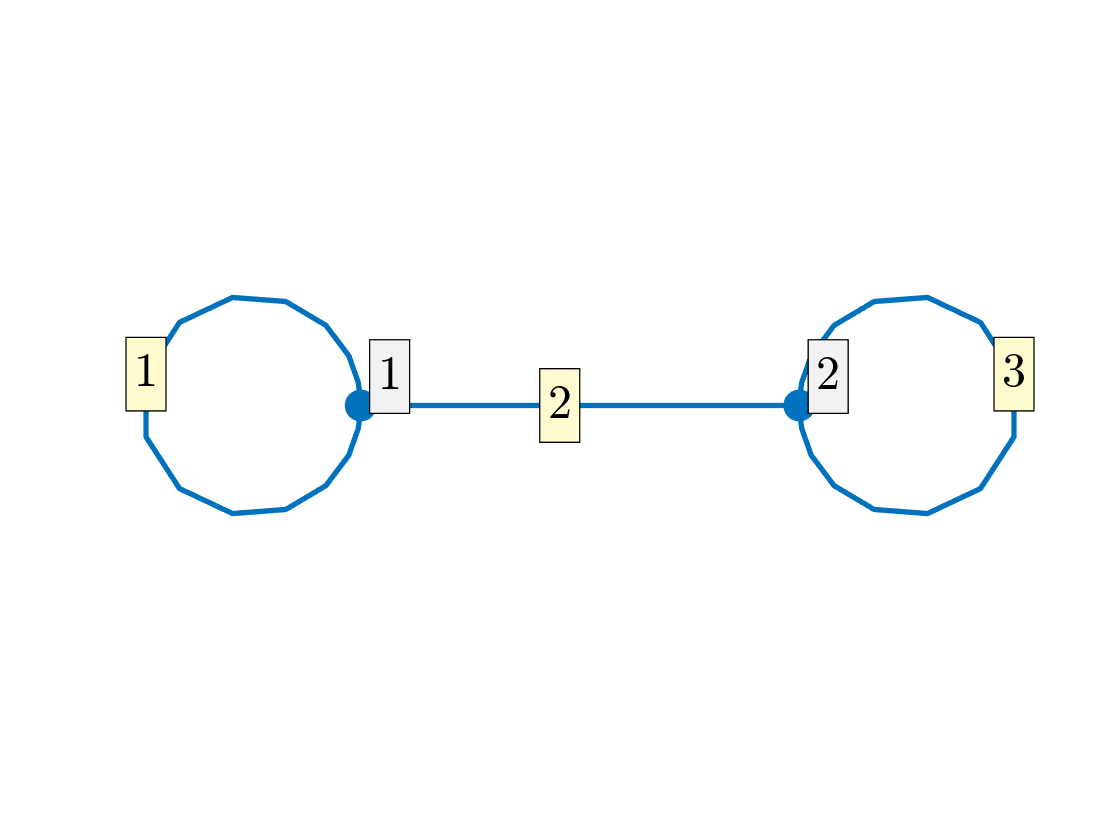

Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nX',16);
Phi.plot('layout')

## Define the function

Defining the non-linear Schrodinger equation on Phi.

nEdges = length(Phi.L);   % Number of edges
nBCs = 2*nEdges;        % Number of BC conditions
[~,~,n] = Phi.nx;         % Number of total x points

A = Phi.laplacianMatrix;                    % The second spatial derivative operator
B = Phi.weightMatrix;                       % The rectangular collocation or weight matrix
C = [B(1:(n-nBCs),:); A((n-nBCs+1):n,:)];   % Weight matrix diagonal with boundary data in bottom rows

f = @(t,z) 1i * (A*z + B*(2*z.^3  + z)); %(( A*z ) + B*((z.*conj(z)).*z));

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used a **solution to the stationary problem** as an initial condtion and used my version of the DoPri-8 scheme.

dataDir = 'dumbbell\001';
eigNum = 1;
u0 = getFirstSolutionFromEigenfunction(dataDir,eigNum,Phi,f);
tend = 1;
[u,t] = Phi.timeEvolveDAE(f,u0,1e-04,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 1000th data point.

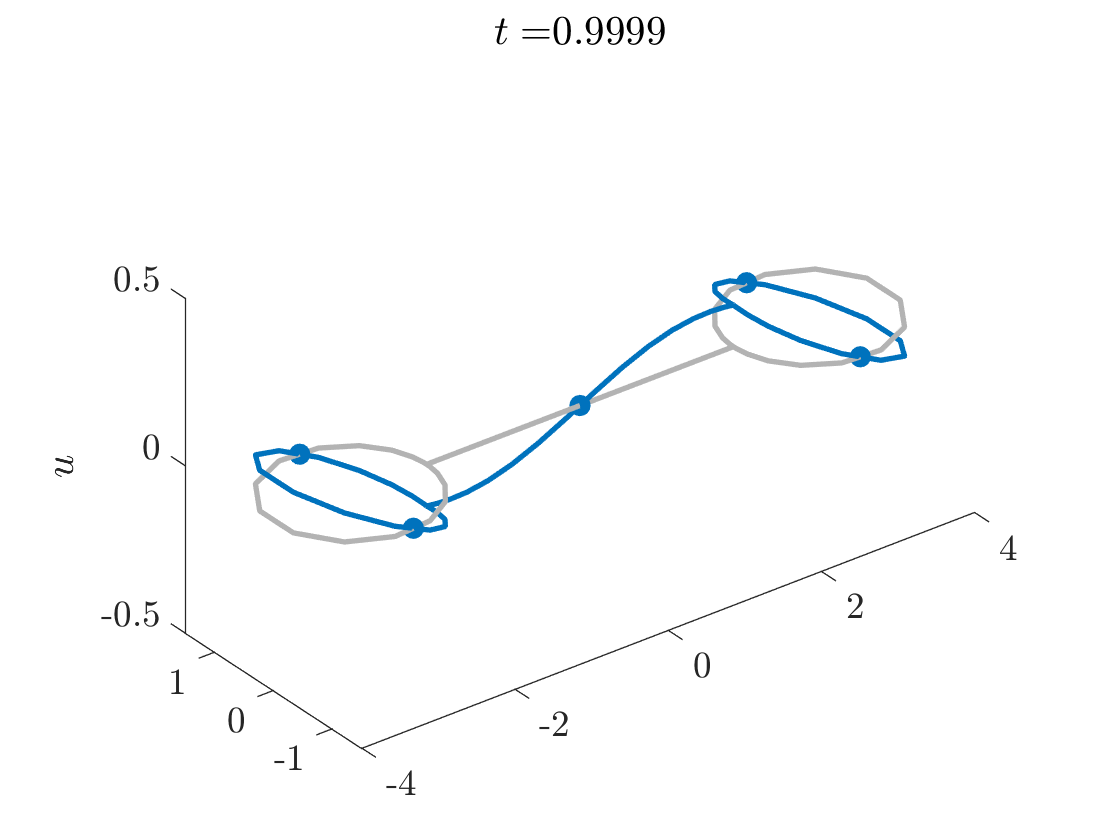

scale = 1000;
for i=1:size(u,2)/scale
    clf
    Phi.plot(u(:,scale*i))
    axis([-4 4 -1.5 1.5 -.5 .5])
    daspect([1 1 .25])
    title(['$t=$',num2str(t(scale*i))])
    zlabel('$u$')
   pause(.0000000001)
end

## Error Analysis

We use an analytical solution to 

uana = @(t) exp(lambda*t).*u0;

error = zeros(1,size(u,2));
for i=1:size(u,2)/scale
    error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
end

disp('The error is:')

The error is:


disp(abs(max(error)))

   1.3916e-12

